clear;
%{
n = 17;
rng(n, "philox");
M = randi([100000 1000000]) / 1000 / sqrt(2)
m = randi([1000 10000]) / 1000 * sqrt(3)
l = randi([100 1000]) / sqrt(5) / 100
%}

M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];



alpha = 10

alpha = 10


cvx_begin sdp

variable P(4, 4)
variable Y1(1, 4)
P > 0.000001 * eye(4);

P*A'+A*P + 2*alpha*P + Y1'*B' +B*Y1 <= 0;


cvx_end

 
Calling SDPT3 4.0: 24 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of sdp    var  =  8,   num. of sdp  blk  =  2
 dim. of free   var  =  4 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.3e+02|5.4e+01|1.8e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.937|0.986|2.7e+01|8.6e-01|7.1e+01| 0.000000e+00  9.699132e-05| 0:0:00| chol  1  1 
 2|0.981|0.929|5.0e-01|7.0e-02|1.3e+00| 0.000000e+00  1.046673e-04| 0:0:00| chol  1  1 
 3|0.892|0.420|5.4e-02|4.1e-02|2.7e-01| 0.000000e+00  9.924969e-05| 0:0:00|

K = Y1 *pinv(P)

K = 1.0e+07 *

    0.7891    0.1537   -1.4651   -0.2679




x_07 = [0.01; 0.01; 0.01; 0.01];
x_0 = x_07;

f = 0;

tspan = [0 40];

% Решение ОДУ
[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end



disp('phi');

phi


max_phi = max(x(:,3))

max_phi = 0.0226

min(x(:,3))

ans = -0.0586

disp('a');

a


max_a = max(x(:,1))

max_a = 0.0358

min(x(:,1))

ans = -0.1084

disp('u');

u


max_u = max(u)

max_u = 2.6352e+04

min(u)

ans = -7.9007e+04

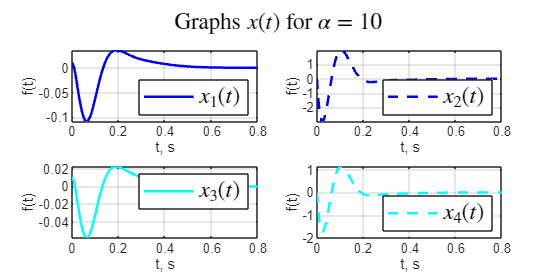



% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',1.5); 
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.8])
grid()

%figure('Position', [100 100 800 400])
subplot(2,2,2);
plot(t, x(:,2), 'b--', 'LineWidth',1.5); 
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.8])
grid()

subplot(2,2,3);
plot(t, x(:,3), 'c-', 'LineWidth',1.5); 
legend('$x_3 (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.8])
grid()

subplot(2,2,4);
plot(t, x(:, 4), 'c--', 'LineWidth',1.5);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.8])
grid()


sgtitle('Graphs $x(t)$ for $\alpha = 10$','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\4_2_x_10.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

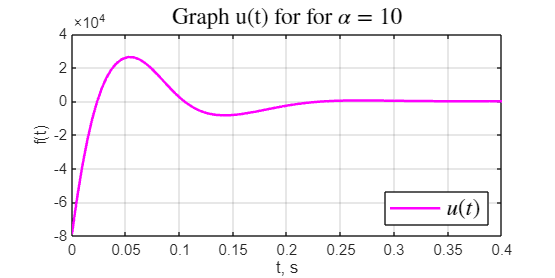





figure('Position', [100 100 800 400])
plot(t, u, 'm-', 'LineWidth',1.5);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
title('Graph u(t) for for $\alpha = 10$','Interpreter','latex',  'FontSize', 14)
xlim([0 0.4])
grid()


full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\4_2_u_10.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);